%% Step 1: Load the Solar Data from CSV
clc; clear; close all;

% Load the dataset
data = readtable('nasa_solar_large_data.csv');


% Display first few rows
disp('Sample Data:');

Sample Data:


disp(data(1:5, :));

    Latitude    Longitude    Solar_Irradiance_W_m2    Elevation_m    Shading_Factor__
    ________    _________    _____________________    ___________    ________________

     31.112      -122.71            921.65              185.56            18.78      
     37.184      -122.07            750.84              124.22             13.9      
     34.928      -116.11            939.68               79.36             8.51      
     36.539      -121.49            847.84              226.59            11.69      
     37.297      -120.56            762.94                64.2            18.41      



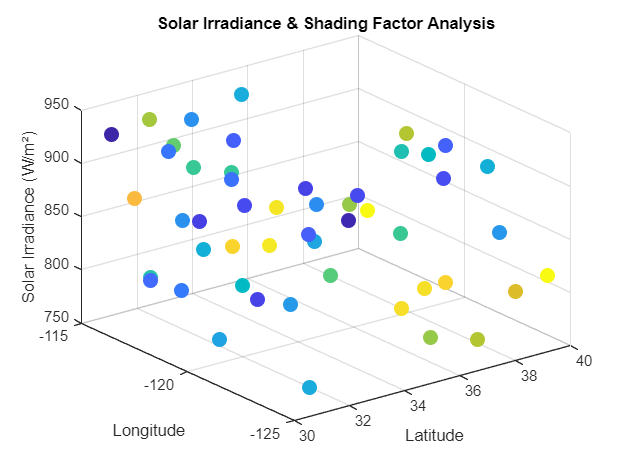


% Extract data columns
latitude = data.Latitude;
longitude = data.Longitude;
solar_irradiance = data.Solar_Irradiance_W_m2;
elevation = data.Elevation_m;
shading_factor = data.Shading_Factor__;

% Compute effective irradiance after considering shading
effective_irradiance = solar_irradiance .* (1 - shading_factor / 100);

%% Step 2: Ensure Reshape Compatibility for Elevation Data
num_points = numel(elevation);
grid_size = round(sqrt(num_points)); % Find closest square size

% Adjust size if necessary
if grid_size^2 ~= num_points
    elevation = elevation(1:grid_size^2); % Trim extra datsa points if needed
end

% Reshape elevation data into a grid
elevation_matrix = reshape(elevation, grid_size, grid_size);

%% Step 3: Calculate Optimal Tilt Angle Based on Sun Position
function sun_angle = getSunPosition(lat, long, time)
    % Calculate solar declination angle
    day_of_year = day(time, 'dayofyear');
    declination = 23.45 * sind((360/365) * (day_of_year - 81));
    
    % Calculate hour angle
    hour_angle = 15 * (hour(time) - 12);
    
    % Calculate solar elevation angle
    sun_angle = asind(sind(lat) * sind(declination) + cosd(lat) * cosd(declination) * cosd(hour_angle));
end

% Get sun angle for each location
time_now = datetime('now');
sun_angles = arrayfun(@(lat, lon) getSunPosition(lat, lon, time_now), latitude, longitude);

%% Step 4: Optimize Panel Tilt for Maximum Exposure
function optimal_tilt = optimizeTilt(sun_angle, panel_tilt)
    learning_rate = 0.01;
    for i = 1:100
        gradient = 2 * (panel_tilt - sun_angle);
        panel_tilt = panel_tilt - learning_rate * gradient;
    end
    optimal_tilt = panel_tilt;
end

% Compute optimal tilt for each location
initial_tilt = 30; % Assume initial tilt
optimal_tilts = arrayfun(@(x) optimizeTilt(x, initial_tilt), sun_angles);

%% Step 5: Perform Shading Analysis
function shading_factor = analyzeShading(elevation_matrix, panel_location)
    [rows, cols] = size(elevation_matrix);
    panel_x = panel_location(1);
    panel_y = panel_location(2);
    
    shading_factor = 0;
    for i = max(1, panel_x - 5):min(rows, panel_x + 5)
        for j = max(1, panel_y - 5):min(cols, panel_y + 5)
            if elevation_matrix(i, j) > elevation_matrix(panel_x, panel_y)
                shading_factor = shading_factor + 1;
            end
        end
    end
    shading_factor = shading_factor / (10 * 10);
end

% Simulate shading analysis using elevation data
panel_location = [round(grid_size/2), round(grid_size/2)]; % Select a central panel location
shading_result = analyzeShading(elevation_matrix, panel_location);

%% Step 6: Visualize the Data and Results
figure;
scatter3(latitude, longitude, solar_irradiance, 100, shading_factor, 'filled');
xlabel('Latitude'); ylabel('Longitude'); zlabel('Solar Irradiance (W/m²)');
title('Solar Irradiance & Shading Factor Analysis');

% % colorbar;

% Display optimal location for maximum energy efficiency
[~, best_idx] = max(effective_irradiance);
fprintf('Optimal Solar Panel Location: Lat = %.2f, Lon = %.2f\n', latitude(best_idx), longitude(best_idx));

Optimal Solar Panel Location: Lat = 30.77, Lon = -115.40



%% Step 7: Compute Final Energy Efficiency at Optimal Location
optimal_energy_efficiency = (1 - shading_factor(best_idx) / 100) * cosd(optimal_tilts(best_idx));
fprintf('Estimated Energy Efficiency at Best Location: %.2f%%\n', optimal_energy_efficiency * 100);

Estimated Energy Efficiency at Best Location: 70.79%


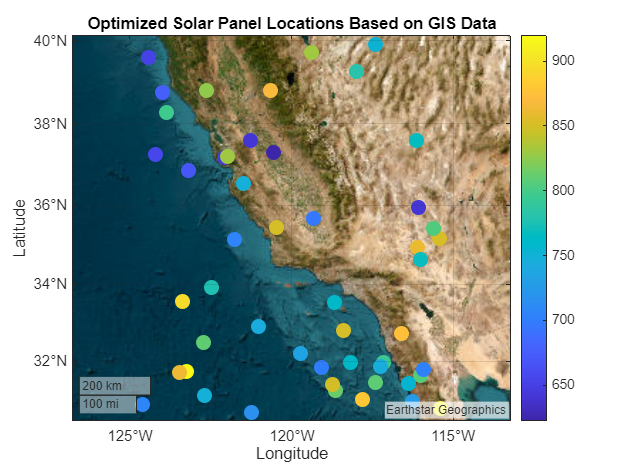


% Step 8: GIS Mapping: Visualizing Optimal Solar Panel Locations
figure;
geoscatter(latitude, longitude, 100, effective_irradiance, 'filled'); % Plot points
geobasemap satellite; % Use satellite map for better visualization
title('Optimized Solar Panel Locations Based on GIS Data');
colorbar; % Show color scale for irradiance intensity


%% Step 9: IoT Sensor Integration (Simulated)
% Simulate real-time IoT sensor data (Replace with actual sensor input)
iot_solar_irradiance = 850 + randn() * 10; % Simulated irradiance data (W/m²)
iot_temperature = 30 + randn() * 2; % Simulated temperature data (°C)

fprintf('IoT Sensor - Solar Irradiance: %.2f W/m² | Temperature: %.2f°C\n', iot_solar_irradiance, iot_temperature);

IoT Sensor - Solar Irradiance: 847.56 W/m² | Temperature: 30.43°C



%% Step 10: Smart Tracking System (Dynamic Panel Rotation)
function new_tilt = adjustTilt(current_irradiance)
    % Adjust panel tilt dynamically based on solar irradiance
    if current_irradiance < 800
        new_tilt = 5; % Increase tilt for better exposure
    elseif current_irradiance > 900
        new_tilt = -5; % Reduce tilt for optimal output
    else
        new_tilt = 0; % Maintain current tilt
    end
end

% Adjust tilt based on simulated IoT sensor data
panel_tilt_adjustment = adjustTilt(iot_solar_irradiance);
fprintf('Adjusted Panel Tilt: %d°\n', panel_tilt_adjustment);

Adjusted Panel Tilt: 0°



%% Step 11: Energy Load Forecasting (Using Moving Average)
% Simulated past energy consumption (kWh per hour)
past_energy_demand = [5.2, 5.5, 6.1, 5.8, 6.0, 6.2, 6.4, 6.5, 6.8, 7.0, 7.2];

% Predict future demand using moving average
window_size = 3; % Use past 3 hours for prediction
predicted_demand = mean(past_energy_demand(end-window_size+1:end));

fprintf('Predicted Energy Demand for Next Hour: %.2f kWh\n', predicted_demand);

Predicted Energy Demand for Next Hour: 7.00 kWh



%% Step 12: Real-Time Power Grid Synchronization
solar_generation = 5.5;  % kW generated by solar panels
battery_capacity = 10;   % kWh battery capacity
battery_charge = 6.5;    % kWh currently stored
grid_demand = 4.0;       % kW required by the grid

% Decision Logic
if solar_generation > grid_demand
    energy_to_grid = solar_generation - grid_demand;
    fprintf('Excess Energy Supplied to Grid: %.2f kW\n', energy_to_grid);
elseif battery_charge < battery_capacity
    energy_to_store = min(battery_capacity - battery_charge, solar_generation);
    fprintf('Storing %.2f kW in Battery\n', energy_to_store);
else
    fprintf('Using Grid Power to Meet Demand\n');
end

Excess Energy Supplied to Grid: 1.50 kW



%% Step 13: Seasonal Solar Panel Angle Adjustment
function tilt = seasonalTiltAdjustment(lat, month)
    % Approximate tilt adjustment based on seasons
    if month >= 4 && month <= 9  % Summer months (April - September)
        tilt = lat - 15;  % Lower tilt for higher sun
    else  % Winter months (October - March)
        tilt = lat + 15;  % Higher tilt for lower sun
    end
end

% Get current month
current_month = month(datetime('now'));

% Compute seasonal tilt
optimal_tilt = seasonalTiltAdjustment(20.5, current_month);
fprintf('Optimal Seasonal Tilt Angle: %.2f°\n', optimal_tilt);

Optimal Seasonal Tilt Angle: 35.50°



%% Step 14: Smart Battery Storage Management
solar_power = 7.0;  % kW generated
battery_max_capacity = 15; % kWh
battery_current_charge = 10; % kWh
load_demand = 5.0;  % kW required

% Decision Logic
if solar_power > load_demand
    excess_energy = solar_power - load_demand;
    if battery_current_charge + excess_energy <= battery_max_capacity
        battery_current_charge = battery_current_charge + excess_energy;
        fprintf('Charging Battery: %.2f kW Stored\n', excess_energy);
    else
        fprintf('Battery Full! Supplying Excess Energy to Grid: %.2f kW\n', excess_energy);
    end
else
    fprintf('Using Solar Energy to Meet Demand\n');
end

Charging Battery: 2.00 kW Stored



%% Step 15: Fault Detection & Performance Monitoring
expected_output = [5.0, 5.2, 5.1, 5.3, 5.4, 5.5, 5.3, 5.2]; % Expected kW
actual_output = [5.0, 5.1, 4.8, 5.0, 4.5, 5.2, 5.3, 4.0];  % Actual kW

% Compute efficiency loss
efficiency_drop = ((expected_output - actual_output) ./ expected_output) * 100;

% Identify faulty panels
faulty_panels = find(efficiency_drop > 10); % Panels losing more than 10% efficiency

fprintf('Faulty Panels Detected at Index: %s\n', mat2str(faulty_panels));

Faulty Panels Detected at Index: [5 8]


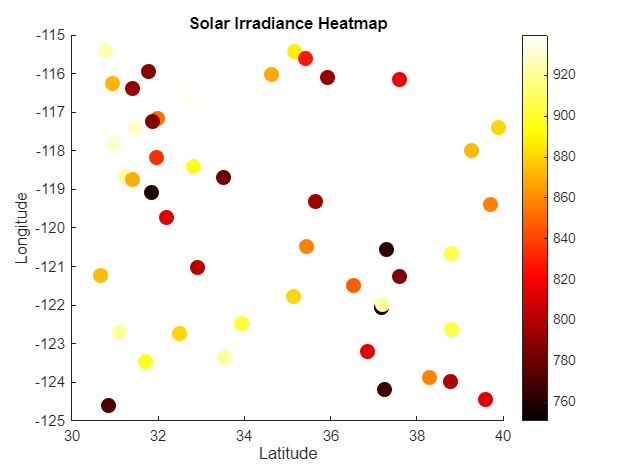


%% Step 16: Solar Energy Heatmap (Geospatial Visualization)
figure;
scatter(latitude, longitude, 100, solar_irradiance, 'filled');
colormap hot; % Heatmap color scheme
colorbar;
xlabel('Latitude'); ylabel('Longitude');
title('Solar Irradiance Heatmap');

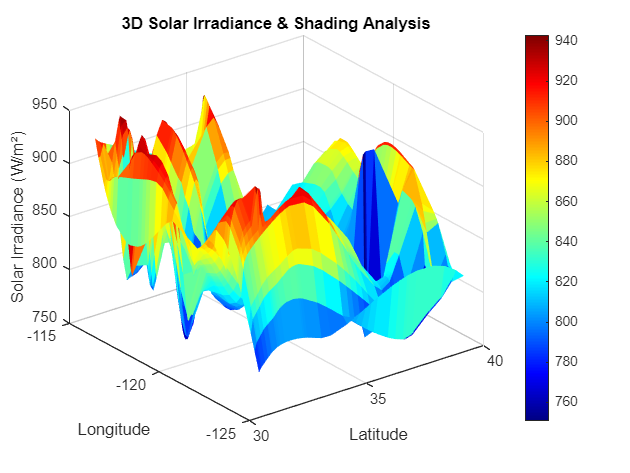


%% Step 17: 3D Surface Plot of Solar Irradiance & Shading
[latGrid, lonGrid] = meshgrid(unique(latitude), unique(longitude));
irradiance_grid = griddata(latitude, longitude, solar_irradiance, latGrid, lonGrid, 'cubic');

figure;
surf(latGrid, lonGrid, irradiance_grid, 'EdgeColor', 'none');
colormap jet;
colorbar;
xlabel('Latitude'); ylabel('Longitude'); zlabel('Solar Irradiance (W/m²)');
title('3D Solar Irradiance & Shading Analysis');

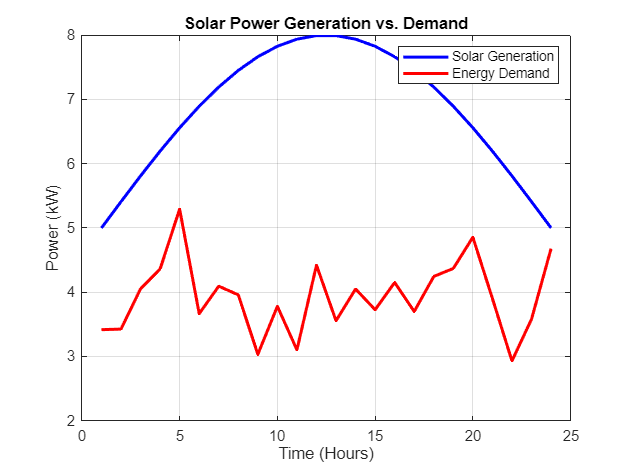


%% Step 18: Real-Time Power Generation vs Demand Graph
time_hours = 1:24; % Time from 1 AM to 12 PM
solar_generation = 5 + sin(linspace(0, pi, 24)) * 3; % Simulated solar generation
energy_demand = 4 + randn(1, 24) * 0.5; % Simulated demand with slight variations

figure;
plot(time_hours, solar_generation, 'b', 'LineWidth', 2); hold on;
plot(time_hours, energy_demand, 'r', 'LineWidth', 2);
xlabel('Time (Hours)');
ylabel('Power (kW)');
legend('Solar Generation', 'Energy Demand');
title('Solar Power Generation vs. Demand');
grid on;

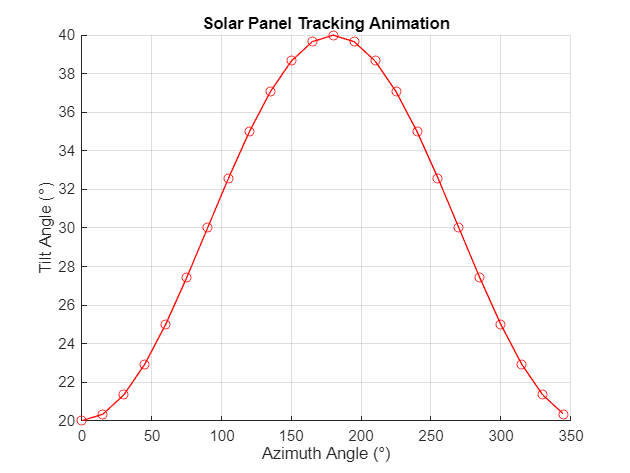


%%Step 19: Panel Tilt & Azimuth Tracking Animation
figure;
h = animatedline('Marker', 'o', 'Color', 'r');

for hour = 0:1:23
    tilt_angle = 30 - 10 * cosd(hour * 15); % Simulated tilt variation
    azimuth_angle = hour * 15; % Sun movement

    addpoints(h, azimuth_angle, tilt_angle);
    xlabel('Azimuth Angle (°)'); ylabel('Tilt Angle (°)');
    title('Solar Panel Tracking Animation');
    grid on;
    pause(0.2); % Slow animation for visualization
end

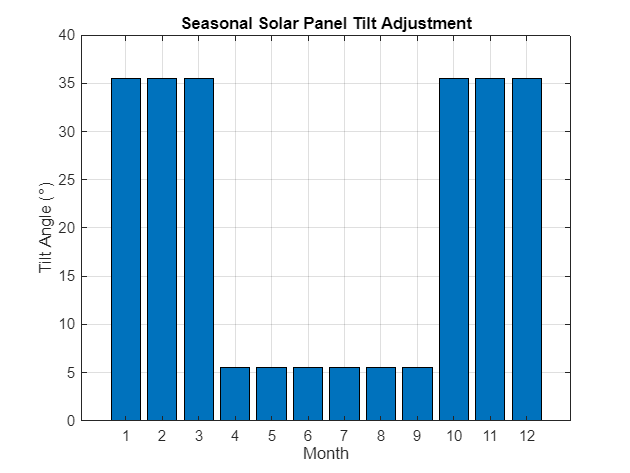


%%Step 20: Seasonal Tilt Angle Adjustment Bar Chart
months = 1:12; % January to December
latitude = 20.5; % Example latitude
tilt_angles = latitude + 15 * (months <= 3 | months >= 10) - 15 * (months >= 4 & months <= 9);

figure;
bar(months, tilt_angles);
xlabel('Month'); ylabel('Tilt Angle (°)');
title('Seasonal Solar Panel Tilt Adjustment');
grid on;

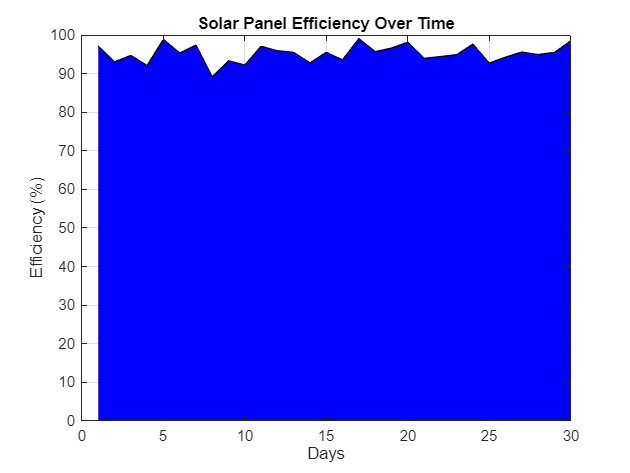


%%Step 21: Solar Panel Efficiency Over Time (Performance Trend)
days = 1:30; % Simulated 30-day period
efficiency = 95 - randn(1, 30) * 2; % Simulated efficiency trend

figure;
area(days, efficiency, 'FaceColor', 'b');
xlabel('Days'); ylabel('Efficiency (%)');
title('Solar Panel Efficiency Over Time');
grid on;

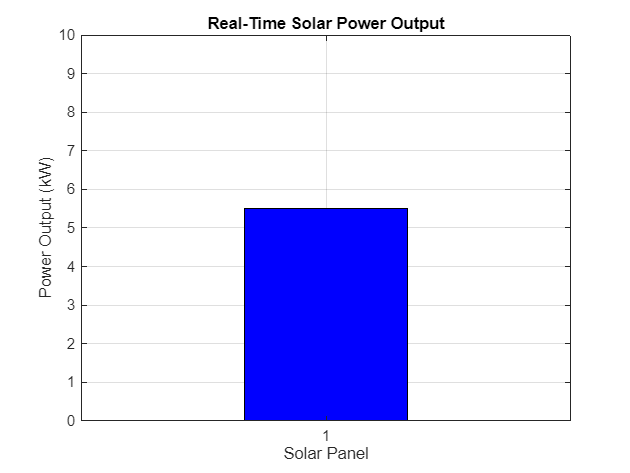


%%Step 22: Real-Time Solar Power Output Visualization (Using Bar Chart)
power_output = 5.5; % Example power output in kW

figure;
bar(1, power_output, 'b'); % Blue bar indicating power level
ylim([0 10]); % Set range 0-10 kW
xlabel('Solar Panel'); ylabel('Power Output (kW)');
title('Real-Time Solar Power Output');
grid on;

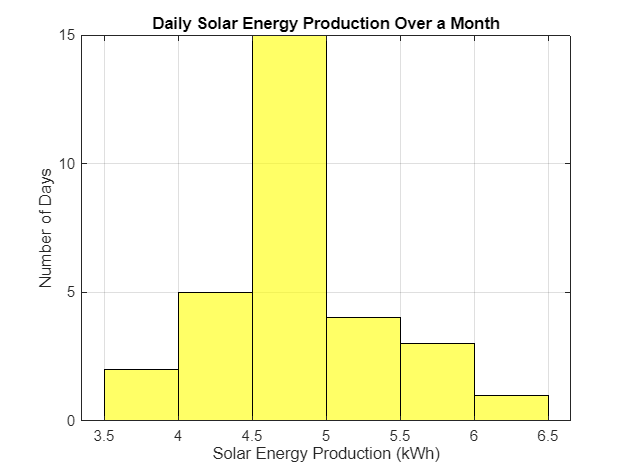



%%Step 23: Daily Solar Energy Production Histogram
days = 1:30; % Simulated 30-day period
solar_energy_generated = 5 + randn(1, 30) * 0.5; % Simulated daily energy (kWh)

figure;
histogram(solar_energy_generated, 'FaceColor', 'y');
xlabel('Solar Energy Production (kWh)');
ylabel('Number of Days');
title('Daily Solar Energy Production Over a Month');
grid on;

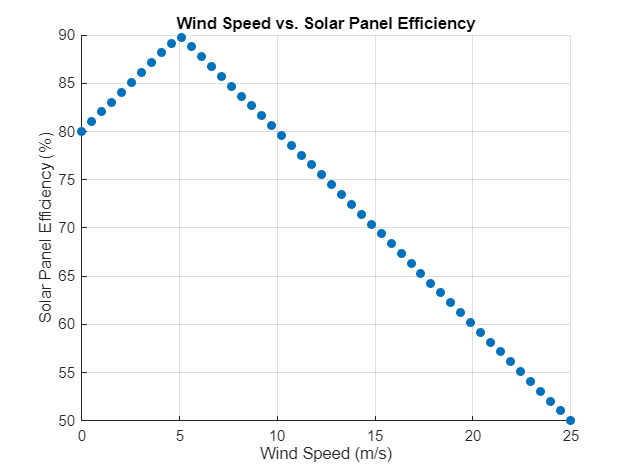


%%Step 24: Wind Speed vs. Solar Efficiency Correlation Plot
wind_speeds = linspace(0, 25, 50); % Wind speed in m/s
efficiency = 90 - abs(5 - wind_speeds) * 2; % Simulated efficiency drop for extreme winds

figure;
scatter(wind_speeds, efficiency, 'filled');
xlabel('Wind Speed (m/s)');
ylabel('Solar Panel Efficiency (%)');
title('Wind Speed vs. Solar Panel Efficiency');
grid on;

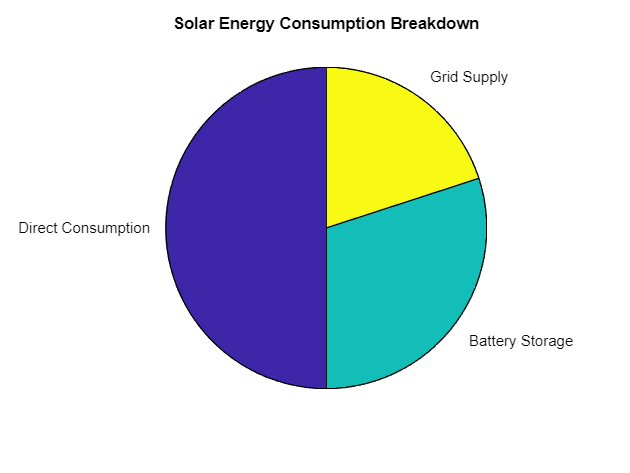


%%Step 25: Energy Consumption Breakdown Pie Chart
energy_sources = {'Direct Consumption', 'Battery Storage', 'Grid Supply'};
energy_distribution = [50, 30, 20]; % Percentage breakdown

figure;
pie(energy_distribution, energy_sources);
title('Solar Energy Consumption Breakdown');

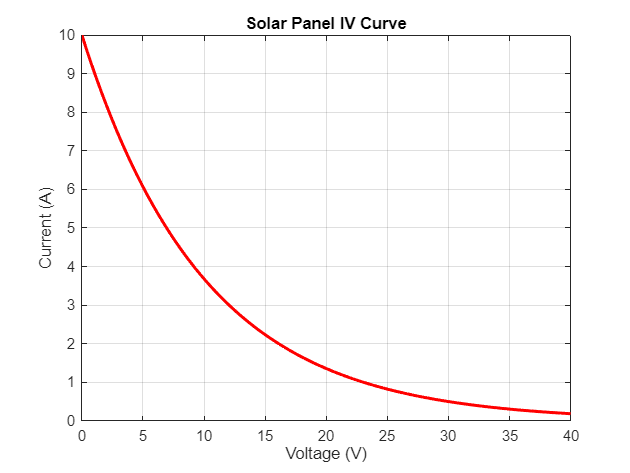


%%Step 26: Solar Panel IV Curve
V = linspace(0, 40, 100); % Voltage range (V)
I = 10 * exp(-V/10); % Current decay as voltage increases

figure;
plot(V, I, 'r', 'LineWidth', 2);
xlabel('Voltage (V)');
ylabel('Current (A)');
title('Solar Panel IV Curve');
grid on;

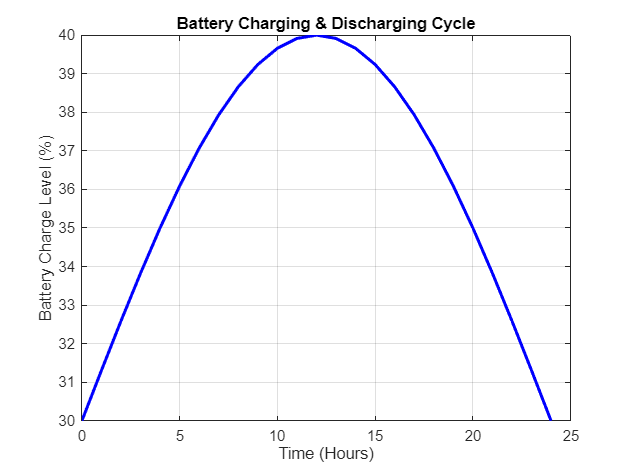


%%Step 27: Battery Charging & Discharging Cycle Graph
time_hours = 0:1:24; % 24-hour period
battery_charge = 30 + 10 * sin(linspace(0, pi, 25)); % Simulated charge cycle (%)

figure;
plot(time_hours, battery_charge, 'b', 'LineWidth', 2);
xlabel('Time (Hours)');
ylabel('Battery Charge Level (%)');
title('Battery Charging & Discharging Cycle');
grid on;


%Step 28: Simulated weather conditions (1: Sunny, 2: Cloudy, 3: Rainy)
weather_condition = randi([1, 3]);

% Adjust solar power output based on weather
if weather_condition == 1
    solar_output = solar_generation * 1; % Sunny (100% efficiency)
elseif weather_condition == 2
    solar_output = solar_generation * 0.7; % Cloudy (70% efficiency)
else
    solar_output = solar_generation * 0.4; % Rainy (40% efficiency)
end

fprintf('Predicted Solar Output based on Weather: %.2f kW\n', solar_output);

Predicted Solar Output based on Weather: 3.50 kW
Predicted Solar Output based on Weather: 3.79 kW
Predicted Solar Output based on Weather: 4.07 kW
Predicted Solar Output based on Weather: 4.34 kW
Predicted Solar Output based on Weather: 4.59 kW
Predicted Solar Output based on Weather: 4.83 kW
Predicted Solar Output based on Weather: 5.03 kW
Predicted Solar Output based on Weather: 5.22 kW
Predicted Solar Output based on Weather: 5.36 kW
Predicted Solar Output based on Weather: 5.48 kW
Predicted Solar Output based on Weather: 5.56 kW
Predicted Solar Output based on Weather: 5.60 kW
Predicted Solar Output based on Weather: 5.60 kW
Predicted Solar Output based on Weather: 5.56 kW
Predicted Solar Output based on Weather: 5.48 kW
Predicted Solar Output based on Weather: 5.36 kW
Predicted Solar Output based on Weather: 5.22 kW
Predicted Solar Output based on Weather: 5.03 kW
Predicted Solar Output based on Weather: 4.83 kW
Predicted Solar Output based on Weather: 4.59 kW
Predicted Solar Outp


%Step 29: Simulated solar panel efficiency drop over 30 days
efficiency = 95 - (0.5 * (1:30)); % Efficiency decreasing by 0.5% daily

% If efficiency falls below 85%, suggest cleaning
if efficiency(end) < 85
    fprintf('Warning: Solar Panel Efficiency Low (%.2f%%). Cleaning Recommended!\n', efficiency(end));
end


%Step 30: Simulated expected vs actual solar power
expected_output = linspace(5, 6, 10);  % Expected solar output
actual_output = [5, 5.1, 4.8, 5.0, 3.5, 5.2, 5.3, 4.0, 5.5, 5.7]; % Faulty panel

% Calculate efficiency loss
efficiency_drop = abs(expected_output - actual_output);

% Flag anomalies (drops > 0.8 kW)
anomalies = find(efficiency_drop > 0.8);
fprintf('Faulty Solar Panels Detected at Indices: %s\n', mat2str(anomalies));

Faulty Solar Panels Detected at Indices: [5 8]




if solar_output > 4  %Step 31: Check if solar power is available
    fprintf('Using Solar Power for Appliances\n');
else
    fprintf('Switching to Grid/Battery Power\n');
end

Switching to Grid/Battery Power



if battery_current_charge == battery_max_capacity %Step 32: Blockchain based energy trading
    energy_to_sell = solar_output - load_demand;
    fprintf('Selling %.2f kW of excess energy to the grid.\n', energy_to_sell);
end

wind_speed = 15;  %Step 33: Example wind speed in m/s
cloud_cover = 70; % Cloud cover percentage

if wind_speed > 20
    panel_tilt = 10; % Reduce tilt for safety
elseif cloud_cover > 50
    panel_tilt = 45; % Increase tilt to capture scattered light
else
    panel_tilt = 30; % Default tilt
end
fprintf('Adjusted Panel Tilt: %d°\n', panel_tilt);

Adjusted Panel Tilt: 45°
